# Rectification - Shape Reconstruction with DLT

Rectification of an image using DLT from a square

## Corresponding points

To find the transformation matrix we are required to know the location of 4 points in the image we have and the corresponding on the original one. This is in general unknown, since we don't have the original scene, but in this case we can rectify a square: we can extract 4 edges of the image of a square and map them to the coordinates of any square.

Be careful when selecting the points to do so in clock- or anticlock-wise order, to match the scene points definition.

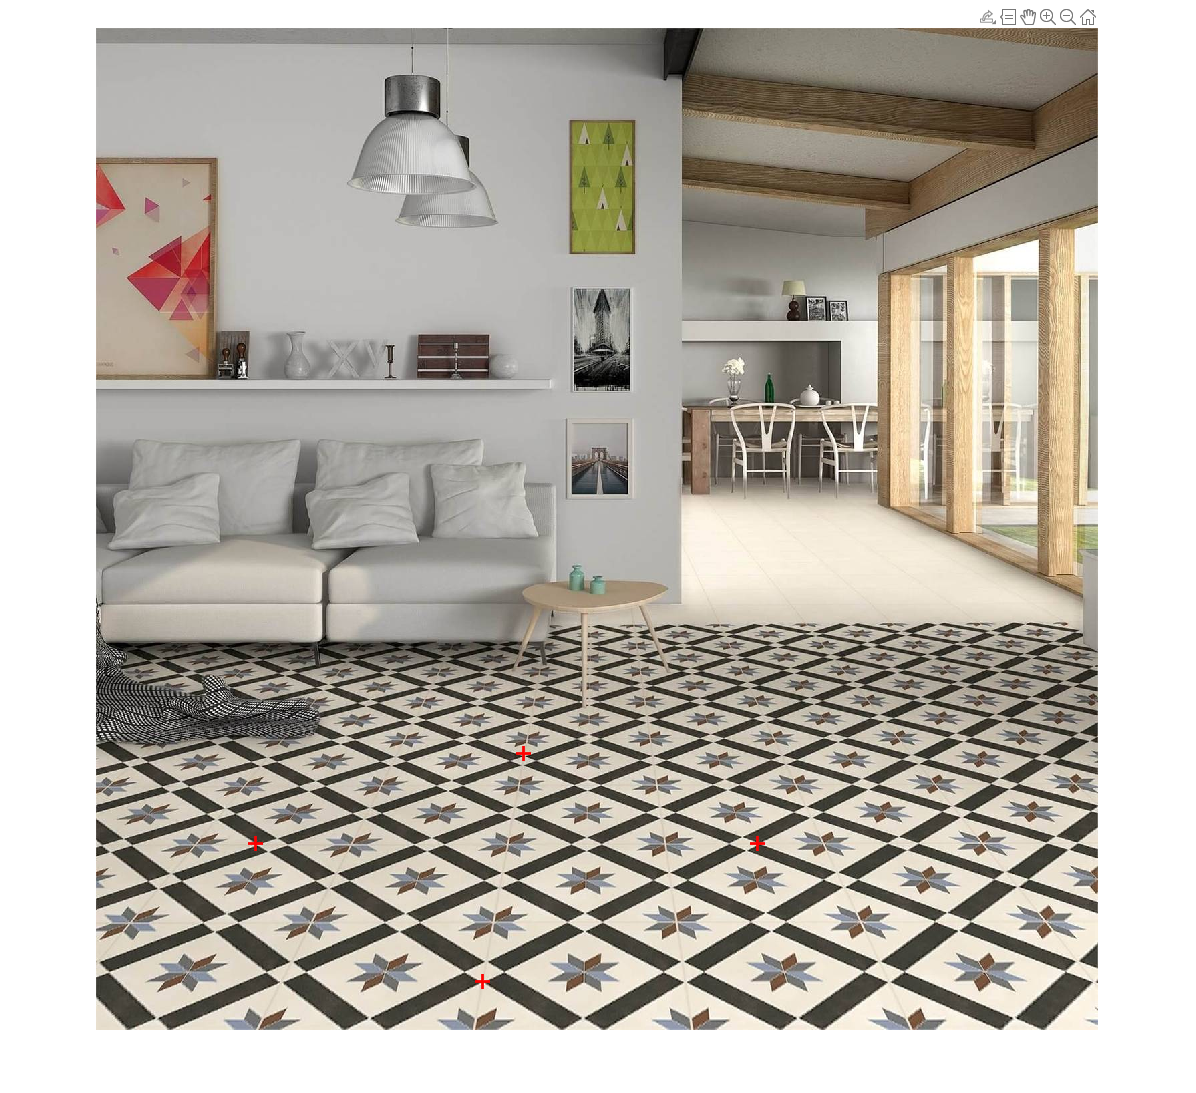

cd ~/Documents/Polimi/IACV/
I = imread('images/floor_tiles_hq.jpeg');
figure(1), imshow(I); figure(1), hold on;
[ptsx, ptsy] = getpts();
plot(ptsx, ptsy, 'r+', MarkerSize=10, LineWidth=2);

We are going to create the matrices with our sets of points

% the points on our image
aP = [ptsx(1); ptsy(1); 1];
bP = [ptsx(2); ptsy(2); 1];
cP = [ptsx(3); ptsy(3); 1];
dP = [ptsx(4); ptsy(4); 1];

Ysquare = [aP bP cP dP];

% the corresponding points on the (similarity of the) original scene
aS = [1; 1; 1];
bS = [1; 500; 1];
cS = [500; 500; 1];
dS = [500; 1; 1];

Xsquare = [aS bS cS dS];

## Homography Estimation - DLT

Follow the function defined below to read what are the steps to follow to perform DLT

H = dlt(Xsquare, Ysquare)

H =    -0.0003   -0.0005    0.8896
    0.0003   -0.0004    0.4567
   -0.0000    0.0000   -0.0002


We may want to check the correctness of our computation by mapping our points from the rectified scene to the image. After a rescale, we will be able to compare the points obtained

Ycheck = H\Xsquare;       % A\B solves the system of linear equations A*x = B (equivalent to inv(A)*b)
% normalize the result and the initial vector to compare them
Ycheck = Ycheck(1:2,:) ./ Ycheck(3, :);
Ycheck = Ycheck .* Ysquare(3, :);       % should be multiplying by one, but you never know...
Ynorm = Ysquare(1:2,:) .* Ysquare(3, :);
Ycheck - Ynorm < power(10, -7)

ans = 2×4 logical array
   1   1   1   1
   1   1   1   1


## Image representation

To visualize the result we need to map the points of the image according to H.

Follow the function defined below to read what are the steps to follow to perform the image distortion

I2 = warp(I, H);

And show it

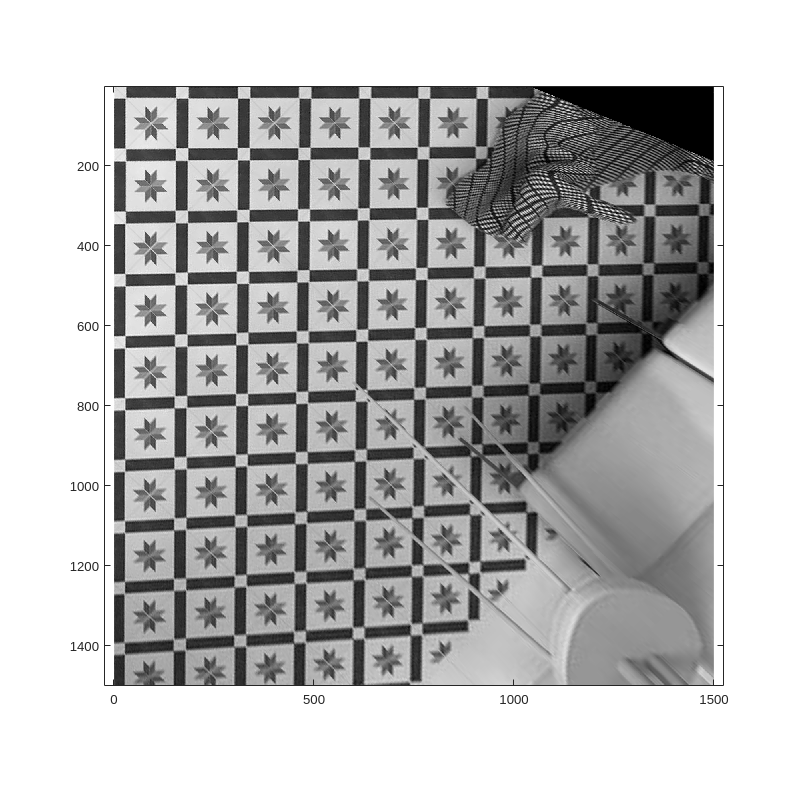

figure(2), imagesc(I2), colormap gray, axis equal, hold off;

## Preconditioning

To avoid numeric imprecisions due to the high range of values

We will center the data with:

tx = mean(Ysquare(1,:));
ty = mean(Ysquare(2,:));

and shrink the domain with:

s = mean(std(Xsquare,[], 2));

We can then apply the transformation matrices (scaling + translation)

T = [1/s 0 -tx/s; 0 1/s -ty/s; 0 0 1];
Xc = T * Xsquare;
Yc = T * Ysquare;

Calculate the homography matrix and transform it back

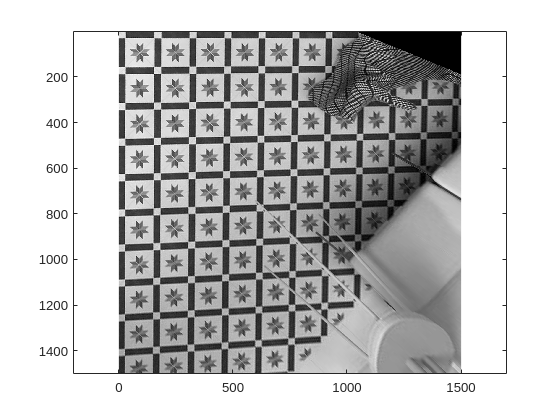

Hc = dlt(Xc, Yc);
Hprec = inv(T) * Hc * T;
%
I2prec = warp (I, Hprec);
figure(3), imagesc(I2prec), colormap gray, axis equal, hold off;

# Auxiliary functions

## DLT

function H = dlt(X, Y)

We are going to compute the design matrix A, collecting the data about X and Y

    n = size(X,2);
    A = zeros(2*n, 9);
    cnt = 1;
    
    for row = 1:n           
        y = Y(:, row)';
        x = X(:, row);
        A(cnt, :) = [0, 0, 0, x(3)*y, -x(2)*y];
        A(cnt + 1, :) = [x(3)*y, 0, 0, 0, -x(1)*y];
        cnt = cnt + 2;
    end


Using SVD we are solving the minimization problem

    [~, ~, V] = svd(A);
    h = V(:, end);          % the values of H are stored in the last column, but need reordering
    H = reshape(h, [3, 3])';
end

## Image warp

To apply the transformation to the image to be able to visualize it

Create the gid with the points we are going to calculate

function Iwarp = warp(I, H)
    [x, y] = meshgrid(1:1500, 1:1500);
    % we will treat with a "vectorization" of a matrix
    x_vect = x(:)';
    y_vect = y(:)';
    % make homogeneous
    X = [x_vect; y_vect; ones(size(x_vect))];

Apply the inverse tranform

    Y = H\X;                                        
    Y = Y ./ repmat(Y(end,:), size(Y, 1), 1);       % projective division
    Y = Y(1:end-1, :);                               % remove last row

Now we can reshape back

    xi = reshape(Y(1,:), size(x,1), []);
    yi = reshape(Y(2,:), size(y,1), []);

Get the new image

    Igray = rgb2gray(I);
    Iwarp = interp2(1:size(Igray, 2), 1:size(Igray, 1), double(Igray), xi, yi, 'linear', 0);
    cast(Iwarp, class(Igray));
end